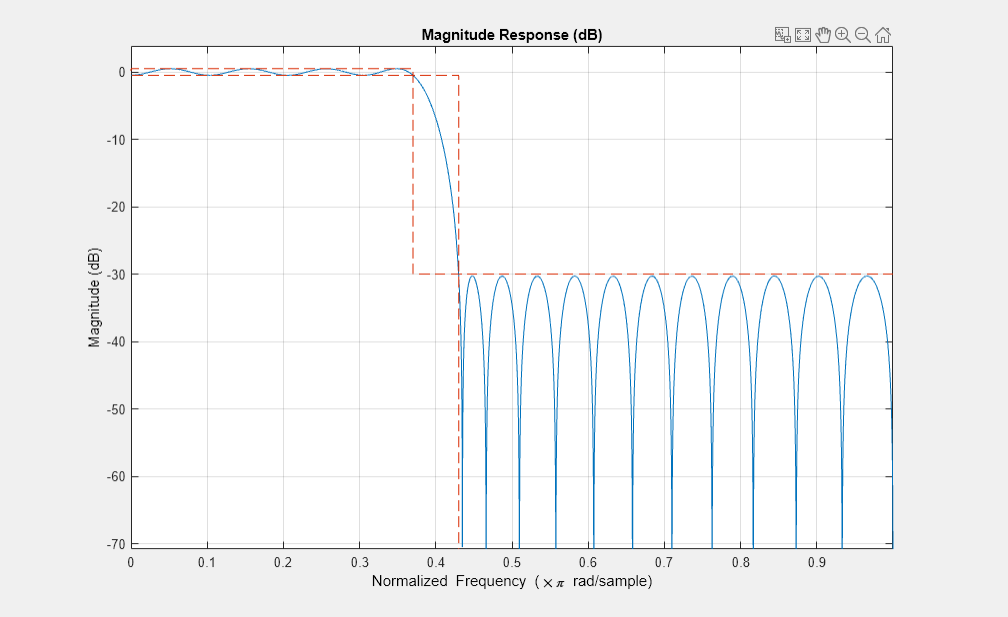

Fpass = 0.37; 
Fstop = 0.43;
Ap = 1;
Ast = 30;

d = designfilt('lowpassfir','PassbandFrequency',Fpass,...
  'StopbandFrequency',Fstop,'PassbandRipple',Ap,'StopbandAttenuation',Ast);

hfvt = fvtool(d);

The resulting filter order can be queried using the `filtord` function.

N = filtord(d)

N = 39

You can use the `info` function to get information about the parameters used to design the filter.

info(d)

ans = 16x32 char array
    'FIR Digital Filter (real)       '
    '-------------------------       '
    'Filter Length  : 40             '
    'Stable         : Yes            '
    'Linear Phase   : Yes (Type 2)   '
    '                                '
    'Design Method Information       '
    'Design Algorithm : Equiripple   '
    '                                '
    'Design Specifications           '
    'Sample Rate     : 2 (normalized)'
    'Response        : Lowpass       '
    'Stopband Edge   : 0.43          '
    'Passband Edge   : 0.37          '
    'Stopband Atten. : 30 dB         '
    'Passband Ripple : 1 dB          '


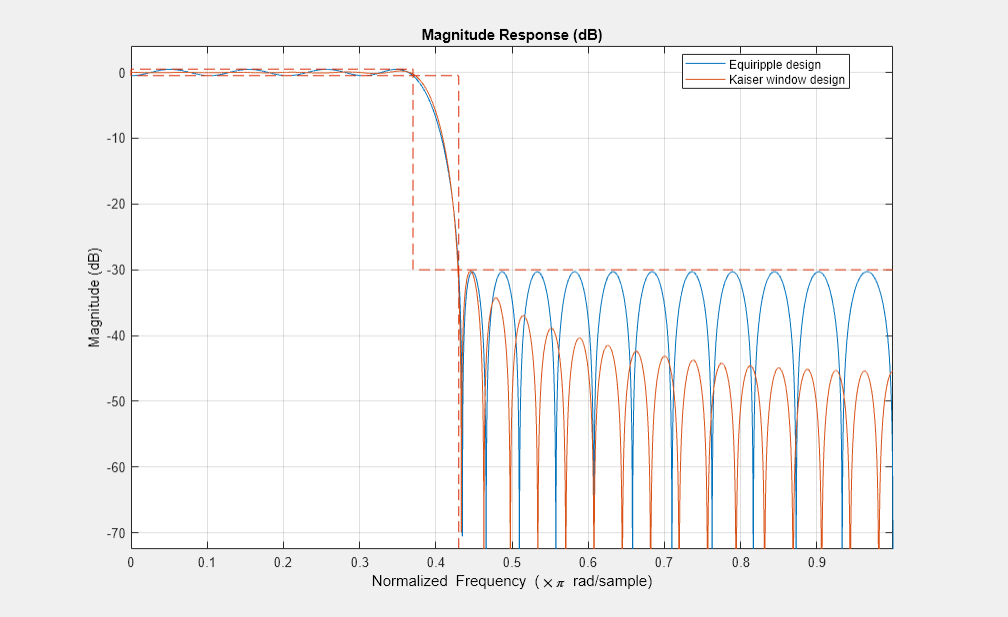

dk = designfilt('lowpassfir','PassbandFrequency',Fpass,...
  'StopbandFrequency',Fstop,'PassbandRipple',Ap,...
  'StopbandAttenuation',Ast, 'DesignMethod', 'kaiserwin');

addfilter(hfvt,dk);
legend(hfvt,'Equiripple design', 'Kaiser window design')


N = filtord(dk)

N = 52

**Specifying Frequency Parameters in Hertz**

If you know the sample rate at which the filter will operate, you can specify the sample rate and the frequencies in hertz. Redesign the minimum-order equiripple filter for a sample rate of 2 kHz.

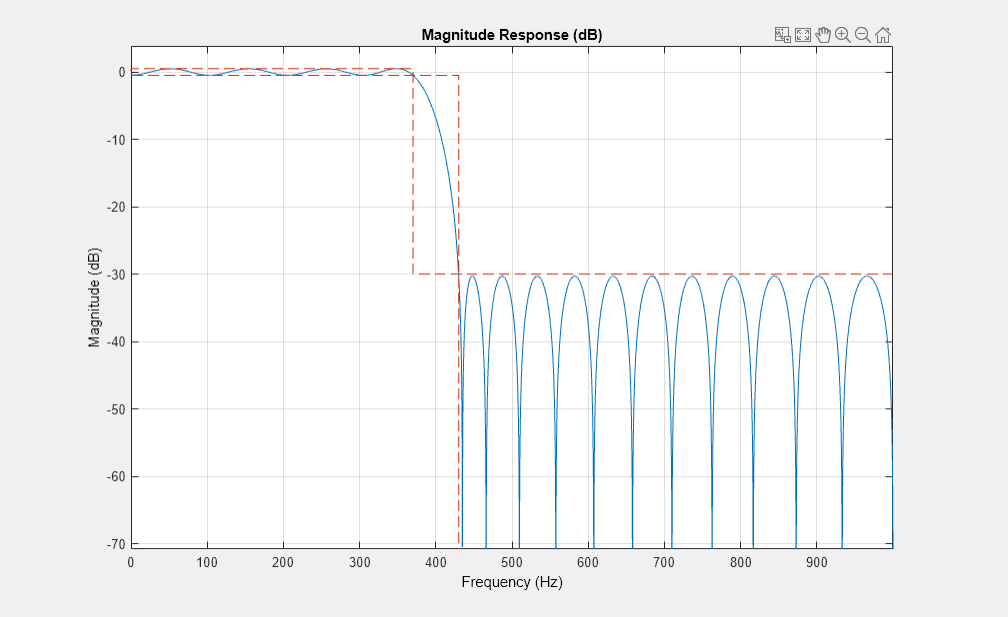

Fpass = 370;
Fstop = 430;
Ap = 1;
Ast = 30;
Fs = 2000; 

d = designfilt('lowpassfir','PassbandFrequency',Fpass,...
  'StopbandFrequency',Fstop,'PassbandRipple',Ap,...
  'StopbandAttenuation',Ast,'SampleRate',Fs);
  
hfvt = fvtool(d);

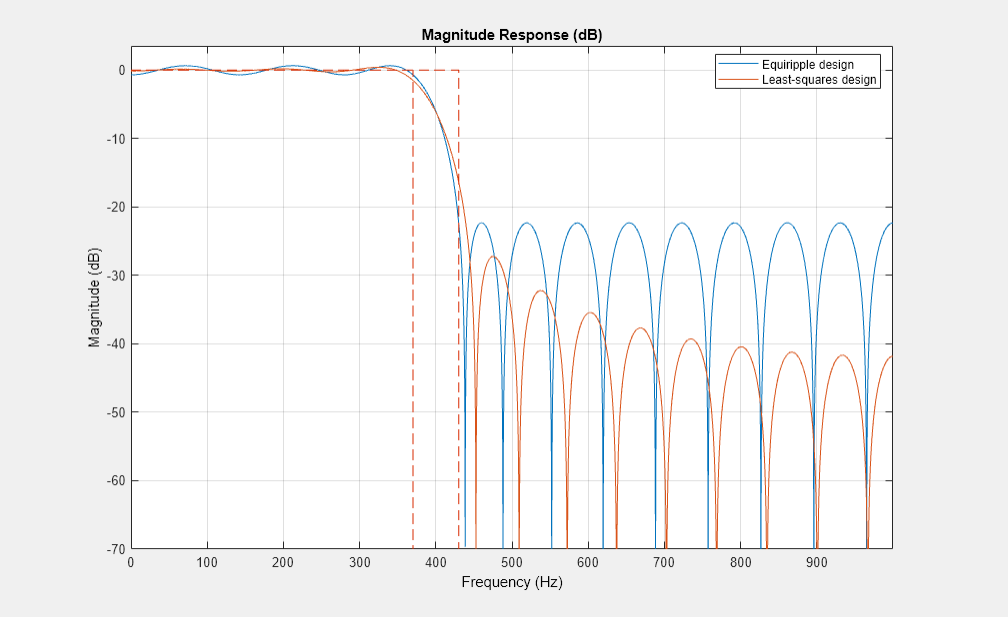

N = 30;
Fpass = 370;
Fstop = 430;
Fs = 2000; 

% Design method defaults to 'equiripple' when omitted
deq = designfilt('lowpassfir','FilterOrder',N,'PassbandFrequency',Fpass,...
  'StopbandFrequency',Fstop,'SampleRate',Fs);

dls = designfilt('lowpassfir','FilterOrder',N,'PassbandFrequency',Fpass,...
  'StopbandFrequency',Fstop,'SampleRate',Fs,'DesignMethod','ls');

hfvt = fvtool(deq,dls);
legend(hfvt,'Equiripple design', 'Least-squares design')

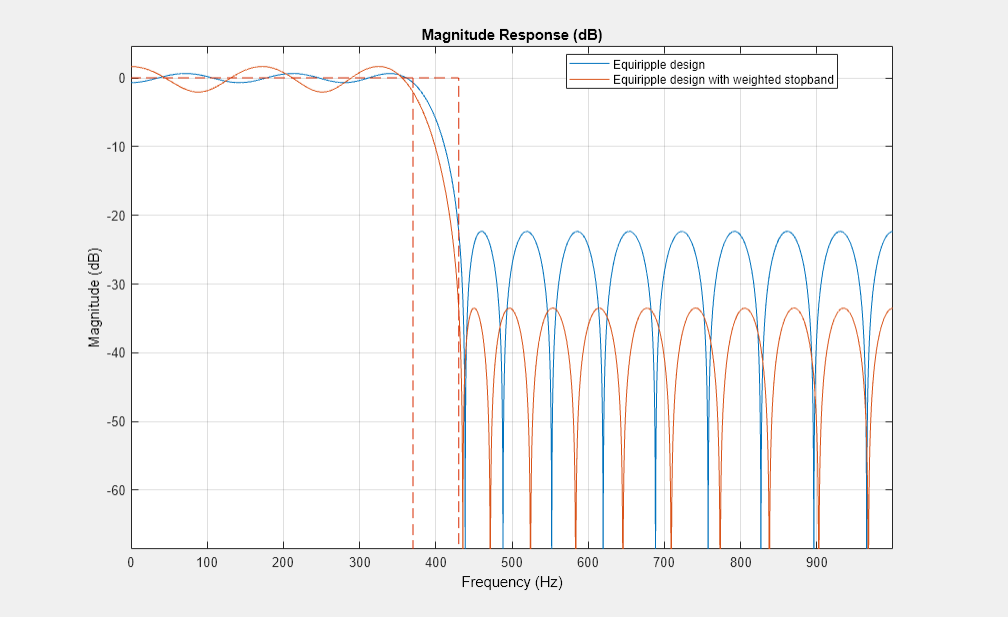

deqw = designfilt('lowpassfir','FilterOrder',N,'PassbandFrequency',Fpass,...
  'StopbandFrequency',Fstop,'SampleRate',Fs,...
  'PassbandWeight',1,'StopbandWeight',10);

hfvt = fvtool(deq,deqw);
legend(hfvt,'Equiripple design', 'Equiripple design with weighted stopband')

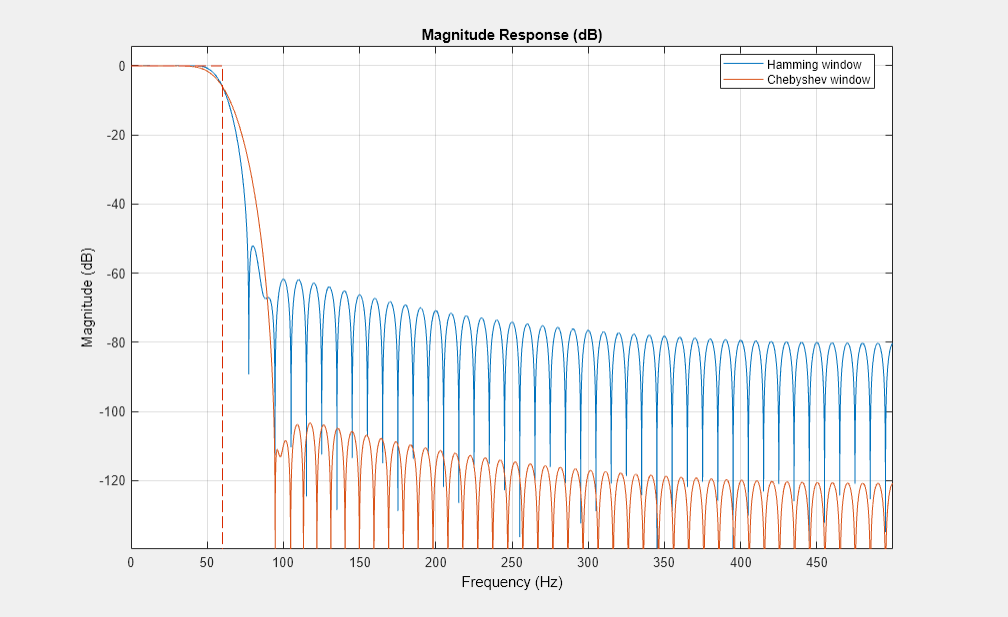

dhamming = designfilt('lowpassfir','FilterOrder',100,'CutoffFrequency',60,...
  'SampleRate',1000,'Window','hamming');

dchebwin = designfilt('lowpassfir','FilterOrder',100,'CutoffFrequency',60,...
  'SampleRate',1000,'Window',{'chebwin',90});

hfvt = fvtool(dhamming,dchebwin);
legend(hfvt,'Hamming window', 'Chebyshev window')

Fp = 100;
Fst = 300;
Ap = 1;
Ast = 60;
Fs = 2e3;

dbutter = designfilt('lowpassiir','PassbandFrequency',Fp,...
  'StopbandFrequency',Fst,'PassbandRipple',Ap,...
  'StopbandAttenuation',Ast,'SampleRate',Fs,'DesignMethod','butter');

dcheby1 = designfilt('lowpassiir','PassbandFrequency',Fp,...
  'StopbandFrequency',Fst,'PassbandRipple',Ap,...
  'StopbandAttenuation',Ast,'SampleRate',Fs,'DesignMethod','cheby1');

dcheby2 = designfilt('lowpassiir','PassbandFrequency',Fp,...
  'StopbandFrequency',Fst,'PassbandRipple',Ap,...
  'StopbandAttenuation',Ast,'SampleRate',Fs,'DesignMethod','cheby2');

dellip = designfilt('lowpassiir','PassbandFrequency',Fp,...
  'StopbandFrequency',Fst,'PassbandRipple',Ap,...
  'StopbandAttenuation',Ast,'SampleRate',Fs,'DesignMethod','ellip');

FilterOrders = [filtord(dbutter) filtord(dcheby1) filtord(dcheby2) filtord(dellip)]

FilterOrders =      7     5     5     4


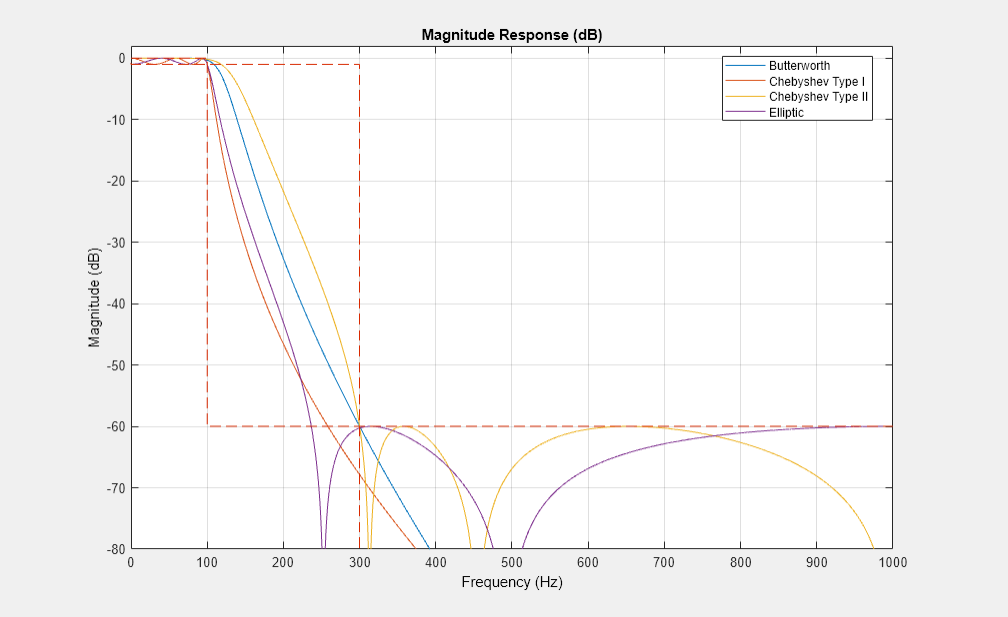

hfvt = fvtool(dbutter,dcheby1,dcheby2,dellip);
zoom(hfvt,[0 1e3 -80 2])

legend(hfvt,'Butterworth', 'Chebyshev Type I',...
  'Chebyshev Type II','Elliptic')

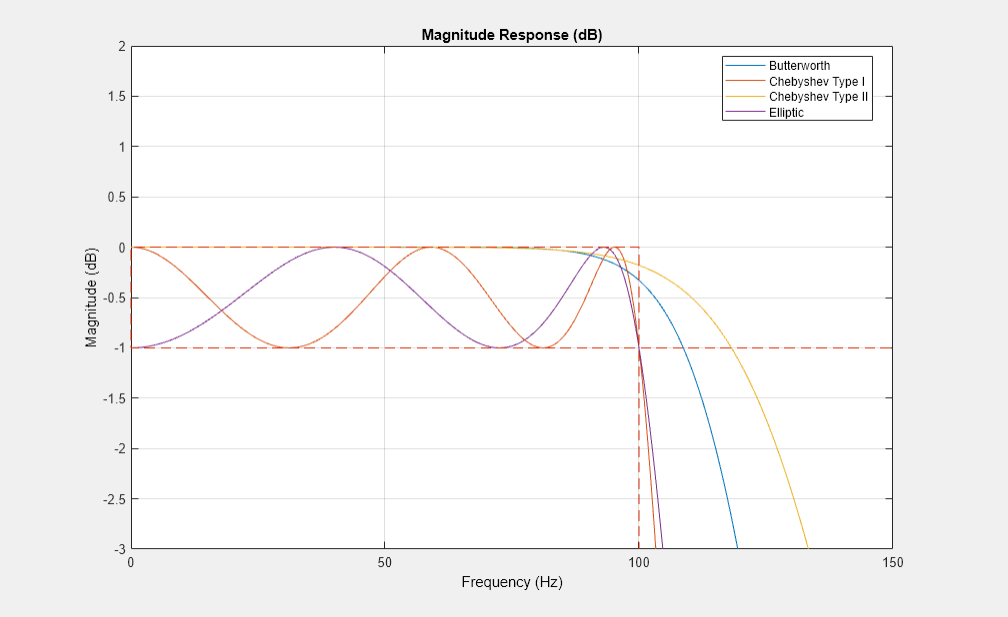

zoom(hfvt,[0 150 -3 2])

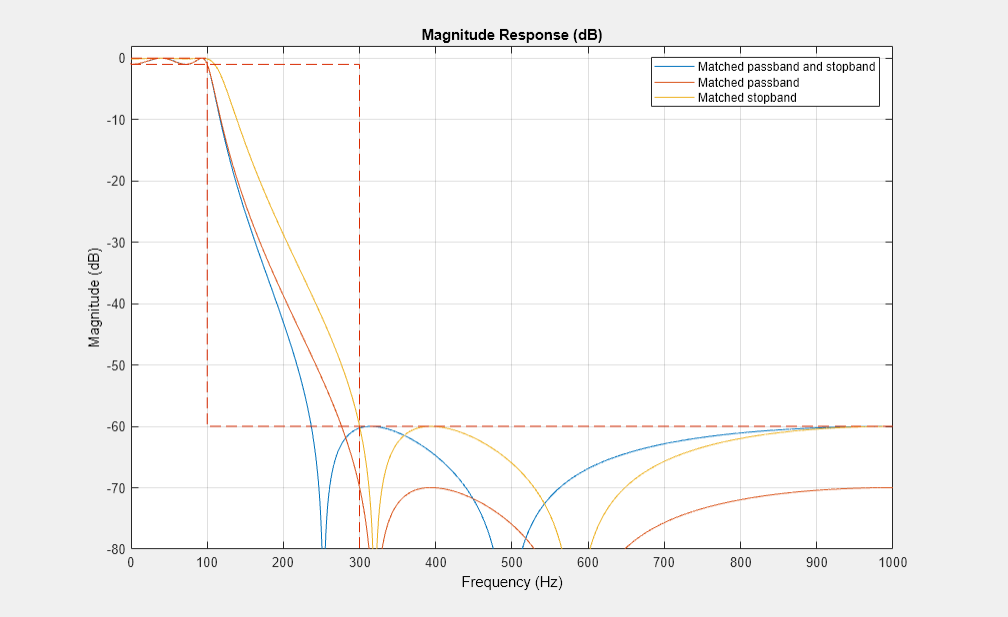

dellip1 = designfilt('lowpassiir','PassbandFrequency',Fp,...
  'StopbandFrequency',Fst,'PassbandRipple',Ap,...
  'StopbandAttenuation',Ast,'SampleRate',Fs,'DesignMethod','ellip',...
  'MatchExactly','passband');

dellip2 = designfilt('lowpassiir','PassbandFrequency',Fp,...
  'StopbandFrequency',Fst,'PassbandRipple',Ap,...
  'StopbandAttenuation',Ast,'SampleRate',Fs,'DesignMethod','ellip',...
  'MatchExactly','stopband');

hfvt = fvtool(dellip, dellip1, dellip2);
legend(hfvt,'Matched passband and stopband','Matched passband',...
  'Matched stopband');
zoom(hfvt,[0 1e3 -80 2])

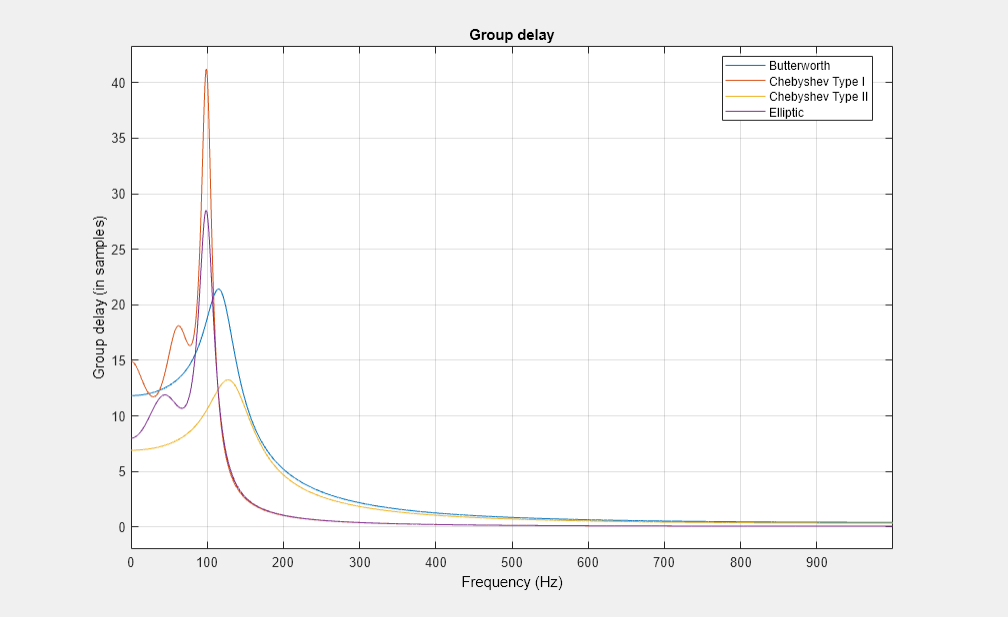

hfvt = fvtool(dbutter,dcheby1,dcheby2,dellip,'Analysis','grpdelay');
legend(hfvt,'Butterworth', 'Chebyshev Type I',...
  'Chebyshev Type II','Elliptic')